%load('C:\Users\franc\OneDrive - unime.it\General\02_2024_CNR_V2G\Dati Comi\Dati Lazio\Other Rome zones_invio\zone_RSM_v19_Cav_zoneUNITOV\zone_UNITOV_mat.mat');
%load('C:\Users\franc\OneDrive - unime.it\General\02_2024_CNR_V2G\Dati Comi\Dati Lazio\Other Rome zones_invio\Zone_1201_Eur\VEMLAZIOUNIROMA2TRIPSzone1201_MAT.mat');
%V2G_table_pre = zoneUniTOV_pre;
%V2G_table_pre=VEMLAZIOUNIROMA2TRIPSzone1201_PRE

hub_nodi = [1201];

%lat e long INSERITI RISPETTO ALL'ORDINE DEI NODI (se il primo nodo è 24, inserire nella prima colonna lat e long dell'hub 24) 
hub_lat =  [41.82500478038935];
hub_long = [12.4666067814776013];

%posizione trovata da Google Maps
lat_rilev = 41.82500478038935;
long_rilev =12.46660678147760;

Grafico mappa

%is_target_zone = ismember(V2G_table_pre.Final_Zone_NO, hub_nodi);
has_valid_sosta_min = ~isnan(V2G_table_pre.stopping_time_check);

% Combina le condizioni usando AND logico
final_condition = has_valid_sosta_min;

% Filtra le righe che soddisfano la sosta in una zona e che quella sia una sosta V2G
V2G_table_soste = V2G_table_pre(final_condition, :);



fig=figure

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 338 560 420]
       Units: 'pixels'

  Show all properties


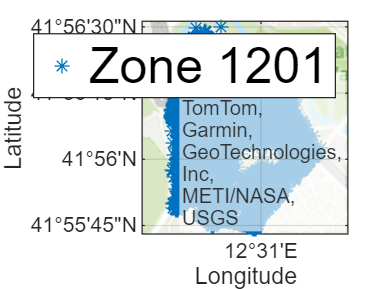

%set(gcf, 'Position', get(0, 'Screensize'));
% Colori per le diverse zone
zone_colors = lines(length(hub_nodi));

% Traccia punti per ciascuna zona
for i = 1:length(hub_nodi)

    %inserimento in un array delle soste nella zona data dall'indice i
    zona = hub_nodi(i);
    %is_target_zone = ismember(V2G_table_soste.Final_Zone_NO, hub_nodi(i));
    soste_zona = V2G_table_soste;

    %inserimento nella mappa
    geoscatter(soste_zona.LatitudineFineViaggio, soste_zona.LongitudineFineViaggio, '*', 'MarkerEdgeColor', zone_colors(i, :), 'DisplayName', ['Zone ' num2str(zona)]);
    hold on
end


% Traccia punti di hub e rilevatori
%geoscatter(hub_lat, hub_long, 100, '*', 'k', 'DisplayName', 'Hubs');
%geoscatter(lat_rilev, long_rilev, 1000, '.', 'r', 'DisplayName', 'Traffic Detector');

% Imposta il basemap e altre proprietà
geobasemap("topographic");
legend show;
legend('FontSize', 20);

hold off;


% Salva il grafico
%savefig('Risultati/Map_stop');
%saveas(gcf, 'Risultati/Map_stop', 'jpg');


